Keyword  

Eo is initial energy

BS is base station

SN is sensor node

0.1 nodes information

clear;
clc;
close all;
SN = 100;  
area_x = 100;
area_y = 100;
area_z = 100;
Eo=0.5;          %initial energy
BS.x = 50;
BS.y= 50;
BS.z= 0;

0.2 nodes creation

for i = 1:SN
    node(i).x = rand*area_x;
    node(i).y = rand*area_y;
    node(i).z = rand*area_z;

    node(i).energy =Eo;


    %distance from Node to BS
    node(i).distanceBS = sqrt(...
        (node(i).x - BS.x)^2 + ...
        (node(i).y - BS.y)^2 + (node(i).z - BS.z)^2);

    %average cludster energy
    node(i).avgClusterEnergy =0;

    %initiating CH coordinate
    node(i).CH_x = 0;
    node(i).CH_y = 0;
    node(i).CH_z = 0;

end
% 0.3 Initial average energy

allEnergy = [node.energy];

initialAvgEnergy = mean([node.energy]);

for i = 1:SN
    node(i).avgClusterEnergy = initialAvgEnergy;
end

0.4 Nodes information packet - there are 9 things 

NodeInfo_Packet = zeros(SN, 9);

for i = 1:SN

    NodeInfo_Packet(i,1) = node(i).x;
    NodeInfo_Packet(i,2) = node(i).y;
    NodeInfo_Packet(i,3) = node(i).z;
    NodeInfo_Packet(i,4) = node(i).energy;
    NodeInfo_Packet(i,5) = node(i).distanceBS;
    NodeInfo_Packet(i,6) = node(i).avgClusterEnergy;
    NodeInfo_Packet(i,7) = node(i).CH_x;
    NodeInfo_Packet(i,8) = node(i).CH_y;
    NodeInfo_Packet(i,9) = node(i).CH_z;

end
X = NodeInfo_Packet;

% 0.3 Initial 3D Sensor Node Deployment
figure;

scatter3([node.x], [node.y], [node.z], ...
    45, 'b', 'filled');

hold on;

% Display Sensor Node numbers
for i = 1:SN

    text(node(i).x, ...
        node(i).y, ...
        node(i).z, ...
        [' ' num2str(i)], ...
        'FontSize', 8);

end

% Plot Base Station
scatter3(BS.x, BS.y, BS.z, ...
    100, 'r', 'filled');

text(BS.x, BS.y, BS.z, ...
    ' BS', ...
    'FontSize', 10);

xlabel('Length of Network (m)');
ylabel('Width of Network (m)');
zlabel('Height of Network (m)');

title('Random 3D Deployment of Sensor Nodes');

grid on;

axis([0 area_x 0 area_y 0 area_z]);

view(3);

hold off;

abcd

% 0.5 Inputs for the First Artificial Neural Network

ANN1_Input = X(:,1:6);



0.7 Normalize First ANN inputs

inputMin = min(ANN1_Input);
inputMax = max(ANN1_Input);

inputRange = inputMax - inputMin;

for j = 1:6

    if inputRange(j) == 0
        ANN1_Input_Norm(:,j) = 0.5;
    else
        ANN1_Input_Norm(:,j) = ...
            (ANN1_Input(:,j) - inputMin(j)) / inputRange(j);
    end

end

0.8 Create reference suitability target

%Energy              → 40%
%Distance to BS      → 30%
%Average cluster energy → 30%

vnkf

energyScore = ANN1_Input_Norm(:,4);

distanceScore = 1 - ANN1_Input_Norm(:,5);

clusterEnergyScore = ANN1_Input_Norm(:,6);

ANN1_Target = ...
    0.4 * energyScore + ...
    0.3 * distanceScore + ...
    0.3 * clusterEnergyScore;

size(ANN1_Target)

ans =    100     1


Preparing,creating,training and generating ANN score

% 8.1 Prepare data for First ANN
ANN1_Input_Train = ANN1_Input_Norm';
ANN1_Target_Train = ANN1_Target';

% 8.2 Number of hidden neurons
hiddenNeurons = 10;

% 8.3 Create First ANN
net1 = feedforwardnet(hiddenNeurons);

% 8.4 Train First ANN
net1 = train(net1, ANN1_Input_Train, ANN1_Target_Train);


% 8.5 Generate ANN suitability score
ANN1_Output = net1(ANN1_Input_Train)';

CH selection

% 9.0 Calculate required number of CHs
p = 0.1;
numberOfCH = floor(p * SN);

% 9.1 Rank nodes according to First ANN score
[sortedScores, sortedIndex] = sort(ANN1_Output, 'descend');

% 9.2 Select highest-scoring nodes as CHs
CH_Index = sortedIndex(1:numberOfCH);

% 9.3 Mark selected nodes as CH
isCH = false(SN,1);
isCH(CH_Index) = true;

% 9.4 Store CH status in node structure
for i = 1:SN
    node(i).isCH = isCH(i);
end

CH region formation

% 10.1 Initialize cluster assignment
clusterAssignment = zeros(SN,1);

% 10.2 Get coordinates of selected CHs
CH_x = [node(CH_Index).x];
CH_y = [node(CH_Index).y];
CH_z = [node(CH_Index).z];

% 10.3 Assign every non-CH node to the nearest CH
for i = 1:SN

    % CH itself does not need to find a CH
    if isCH(i)
        clusterAssignment(i) = find(CH_Index == i);
        continue;
    end

    distanceToCH = zeros(1,numberOfCH);

    for j = 1:numberOfCH

        distanceToCH(j) = sqrt( ...
            (node(i).x - CH_x(j))^2 + ...
            (node(i).y - CH_y(j))^2 + ...
            (node(i).z - CH_z(j))^2);

    end

    [minDistance, nearestCH] = min(distanceToCH);

    clusterAssignment(i) = nearestCH;
end

% 10.4 Calculate cluster size
clusterSize = zeros(numberOfCH,1);

for i = 1:SN
    clusterSize(clusterAssignment(i)) = ...
        clusterSize(clusterAssignment(i)) + 1;
end

 Actual Average Cluster Energy

% 11.1 Initialize average cluster energy
avgClusterEnergy = zeros(numberOfCH,1);

% 11.2 Calculate average residual energy of each cluster
for j = 1:numberOfCH

    clusterNodes = find(clusterAssignment == j);

    clusterEnergy = [node(clusterNodes).energy];

    avgClusterEnergy(j) = mean(clusterEnergy);

end

% 11.3 Store cluster average energy in every node
for i = 1:SN

    clusterID = clusterAssignment(i);

    node(i).avgClusterEnergy = avgClusterEnergy(clusterID);

end

Second ANN

Selected CHs

     │

     ├── CH X

     ├── CH Y

     ├── CH Z

     ├── CH Energy

     ├── Distance to BS

     └── Cluster Size

             │

             ▼

        Second ANN

             │

             ▼

      Main CH suitability

% 12.1 Create Second ANN input matrix
ANN2_Input = zeros(numberOfCH,6);

% 12.2 Fill Second ANN input matrix
for j = 1:numberOfCH

    chNode = CH_Index(j);

    % CH coordinates
    ANN2_Input(j,1) = node(chNode).x;
    ANN2_Input(j,2) = node(chNode).y;
    ANN2_Input(j,3) = node(chNode).z;

    % CH residual energy
    ANN2_Input(j,4) = node(chNode).energy;

    % CH distance to BS
    ANN2_Input(j,5) = node(chNode).distanceBS;

    % Number of nodes in the CH's cluster
    ANN2_Input(j,6) = clusterSize(j);

end

                  All Sensor Nodes

                        │

                        ▼

                  First ANN

                        │

                        ▼

                 CH selection

                        │

                        ▼

                 Cluster formation

                   /          \

                  /            \

         Cluster size      Cluster energy

                  \            /

                   \          /

                    ▼        ▼

                  CH information

                        │

                        ▼

                  Second ANN

now doing ,Normalize the Second ANN Inputs(Min-Max normalization.)

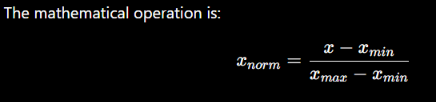

% 13.1 Find minimum and maximum of each Second ANN feature
input2Min = min(ANN2_Input);
input2Max = max(ANN2_Input);

input2Range = input2Max - input2Min;

% 13.2 Create normalized input matrix
ANN2_Input_Norm = zeros(size(ANN2_Input));

% 13.3 Normalize each feature
for j = 1:6

    if input2Range(j) == 0

        ANN2_Input_Norm(:,j) = 0.5;

    else

        ANN2_Input_Norm(:,j) = ...
            (ANN2_Input(:,j) - input2Min(j)) ...
            / input2Range(j);

    end

end

% 13.4 Check dimensions
size(ANN2_Input_Norm)

ans =     10     6


the weights are

Energy             → 40%

Distance to BS     → 30%

Cluster size       → 30%

So the prototype rule is:

Target=0.4(Energy)+0.3(DistanceSuitability)+0.3(ClusterSizeSuitability)

% 14.1 Extract normalized Second ANN features

% Higher energy is better
energyScore = ANN2_Input_Norm(:,4);

% Smaller distance to BS is better
distanceScore = 1 - ANN2_Input_Norm(:,5);

% Smaller cluster size is better
clusterSizeScore = 1 - ANN2_Input_Norm(:,6);


% 14.2 Create prototype Main CH suitability target
ANN2_Target = ...
    0.4 * energyScore + ...
    0.3 * distanceScore + ...
    0.3 * clusterSizeScore;


% 14.3 Check target size
size(ANN2_Target)

ans =     10     1


 Create and Train the Second Artificial Neural Network (ANN)

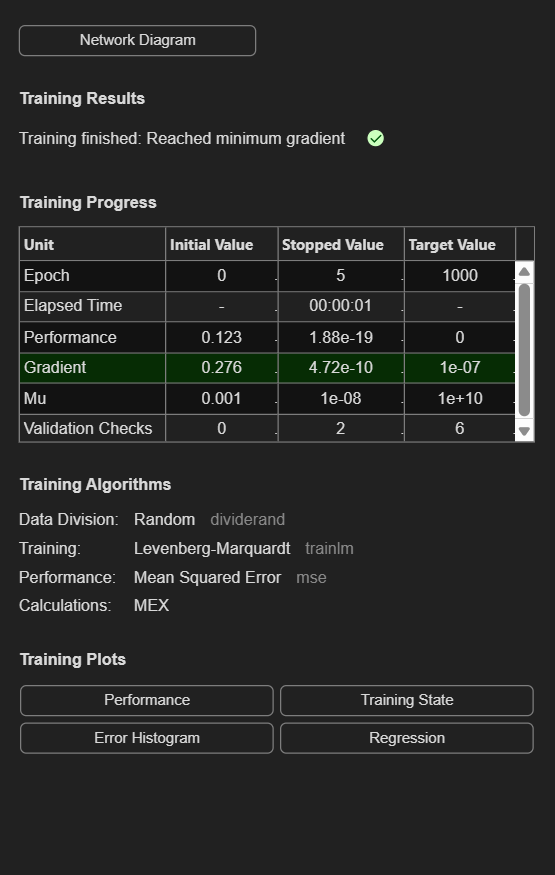

%% 15. Second ANN Creation and Training

% 15.1 Prepare data for Second ANN
ANN2_Input_Train = ANN2_Input_Norm';
ANN2_Target_Train = ANN2_Target';

% 15.2 Number of hidden neurons
hiddenNeurons2 = 10;

% 15.3 Create Second ANN
net2 = feedforwardnet(hiddenNeurons2);

% 15.4 Train Second ANN
net2 = train(net2, ANN2_Input_Train, ANN2_Target_Train);


% 15.5 Generate Main CH suitability score
ANN2_Output = net2(ANN2_Input_Train)';

% 15.6 Check output size
size(ANN2_Output)

ans =     10     1


**First ANN**

`All Sensor Nodes`

`      ↓`

`6 features`

`      ↓`

`First ANN`

`      ↓`

`CH suitability`

`      ↓`

`Select CHs`

**Second ANN**

`Selected CHs`

`      ↓`

`6 features`

`      ↓`

`Second ANN`

`      ↓`

`Main CH suitability`

`      ↓`

`Select Main CH`

This is the key architecture of our current prototype.

**Main CH selection**

%% 16. Main CH Selection

% 16.1 Calculate required number of Main CHs
q = 0.1;

numberOfMainCH = floor(q * numberOfCH);


% 16.2 Rank CHs according to Second ANN score
[~, sortedMainIndex] = ...
    sort(ANN2_Output, 'descend');


% 16.3 Select highest-scoring CHs as Main CHs
MainCH_Index = CH_Index(sortedMainIndex(1:numberOfMainCH));


% 16.4 Mark Main CH status
isMainCH = false(SN,1);

isMainCH(MainCH_Index) = true;


% 16.5 Store Main CH status in node structure
for i = 1:SN

    node(i).isMainCH = isMainCH(i);

end


% 16.6 Store Main CH coordinates and information
for j = 1:numberOfMainCH

    mainNode = MainCH_Index(j);

    MainCH(j).x = node(mainNode).x;
    MainCH(j).y = node(mainNode).y;
    MainCH(j).z = node(mainNode).z;

    MainCH(j).energy = node(mainNode).energy;
    MainCH(j).distanceBS = node(mainNode).distanceBS;

end


% 16.7 Check results
numberOfMainCH

numberOfMainCH = 1

MainCH_Index 

MainCH_Index = 25

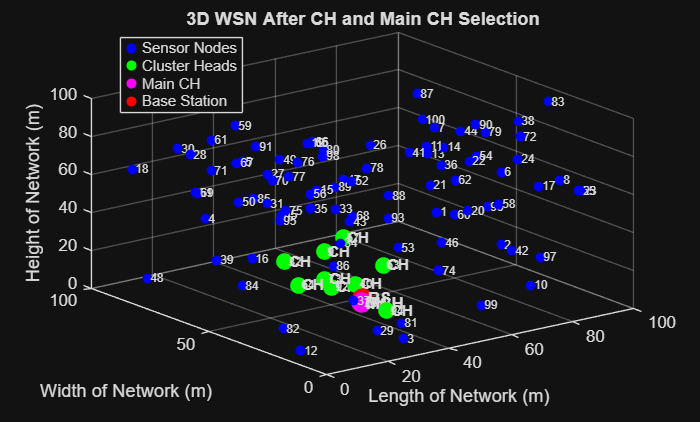


%% 16.7 3D Network After CH and Main CH Selection

figure;

hold on;

% 1. Plot all Sensor Nodes
scatter3([node.x], ...
         [node.y], ...
         [node.z], ...
         35, 'b', 'filled');


% 2. Plot Cluster Heads
CH_x_plot = [node(CH_Index).x];
CH_y_plot = [node(CH_Index).y];
CH_z_plot = [node(CH_Index).z];

scatter3(CH_x_plot, ...
         CH_y_plot, ...
         CH_z_plot, ...
         100, 'g', 'filled');


% 3. Plot Main CH
MainCH_x_plot = [node(MainCH_Index).x];
MainCH_y_plot = [node(MainCH_Index).y];
MainCH_z_plot = [node(MainCH_Index).z];

scatter3(MainCH_x_plot, ...
         MainCH_y_plot, ...
         MainCH_z_plot, ...
         150, 'm', 'filled');


% 4. Plot Base Station
scatter3(BS.x, ...
         BS.y, ...
         BS.z, ...
         150, 'r', 'filled');


% 5. Add Sensor Node numbers
for i = 1:SN

    text(node(i).x, ...
         node(i).y, ...
         node(i).z, ...
         [' ' num2str(i)], ...
         'FontSize', 7);

end


% 6. Add CH labels
for j = 1:numberOfCH

    chNode = CH_Index(j);

    text(node(chNode).x, ...
         node(chNode).y, ...
         node(chNode).z, ...
         ' CH', ...
         'FontSize', 9, ...
         'FontWeight', 'bold');

end


% 7. Add Main CH label
for j = 1:numberOfMainCH

    mainNode = MainCH_Index(j);

    text(node(mainNode).x, ...
         node(mainNode).y, ...
         node(mainNode).z, ...
         ' MCH', ...
         'FontSize', 10, ...
         'FontWeight', 'bold');

end


% 8. Add BS label
text(BS.x, ...
     BS.y, ...
     BS.z, ...
     ' BS', ...
     'FontSize', 10, ...
     'FontWeight', 'bold');


% 9. Axis labels
xlabel('Length of Network (m)');
ylabel('Width of Network (m)');
zlabel('Height of Network (m)');

title('3D WSN After CH and Main CH Selection');


% 10. Grid and axis
grid on;

axis([0 area_x 0 area_y 0 area_z]);

view(3);


% 11. Legend
legend('Sensor Nodes', ...
       'Cluster Heads', ...
       'Main CH', ...
       'Base Station', ...
       'Location', 'best');

hold off;

Updating Node information packet

%% 17. Update Complete Node Information Packet

for i = 1:SN

    % Find which cluster this node belongs to
    clusterID = clusterAssignment(i);

    % Find the Cluster Head of that cluster
    chNode = CH_Index(clusterID);

    % Update CH coordinates
    node(i).CH_x = node(chNode).x;
    node(i).CH_y = node(chNode).y;
    node(i).CH_z = node(chNode).z;

end


% Rebuild the complete 9-feature Node Information Packet
NodeInfo_Packet = zeros(SN,9);

for i = 1:SN

    NodeInfo_Packet(i,1) = node(i).x;
    NodeInfo_Packet(i,2) = node(i).y;
    NodeInfo_Packet(i,3) = node(i).z;
    NodeInfo_Packet(i,4) = node(i).energy;
    NodeInfo_Packet(i,5) = node(i).distanceBS;
    NodeInfo_Packet(i,6) = node(i).avgClusterEnergy;

    NodeInfo_Packet(i,7) = node(i).CH_x;
    NodeInfo_Packet(i,8) = node(i).CH_y;
    NodeInfo_Packet(i,9) = node(i).CH_z;

end


% Display the size of the packet
size(NodeInfo_Packet)

ans =    100     9


TDMA

%% 18. TDMA Slot Assignment

TDMA_Slot = zeros(SN,1);

for j = 1:numberOfCH

    % Find all nodes belonging to this cluster
    clusterNodes = find(clusterAssignment == j);

    % Assign one TDMA slot to each node
    for slot = 1:length(clusterNodes)

        nodeID = clusterNodes(slot);

        TDMA_Slot(nodeID) = slot;

    end

end

disp('Node ID    Cluster ID    TDMA Slot');

Node ID    Cluster ID    TDMA Slot



for i = 1:SN
    fprintf('%7d %12d %12d\n', ...
        i, clusterAssignment(i), TDMA_Slot(i));
end

      1            8            1
      2            5            1
      3            8            2
      4           10            1
      5           10            2
      6            9            1
      7            9            2
      8            5            2
      9            6            1
     10            8            3
     11            9            3
     12            8            4
     13            9            4
     14            9            5
     15           10            3
     16           10            4
     17            5            3
     18           10            5
     19           10            6
     20            8            5
     21            8            6
     22            8            7
     23            5            4
     24            9            6
     25            2            1
     26            9            7
     27            9            8
     28           10            7
     29            8            8
     30       

Energy consumption model

%% 19. Energy Consumption Model

% Packet size
packetLength = 4000;          % bits

% Radio energy parameters
ETX = 50e-9;                  % J/bit
ERX = 50e-9;                  % J/bit
Efs = 10e-12;                 % J/bit/m^2
EDA = 5e-9;                   % J/bit

% Example transmission distance for testing
testDistance = 20;            % meters

% Transmission energy
testTxEnergy = packetLength * ETX + ...
               packetLength * Efs * testDistance^2;

% Reception energy
testRxEnergy = packetLength * ERX;

% Data aggregation energy
testAggregationEnergy = packetLength * EDA;

% Display energy values
fprintf('\n--- Energy Consumption Model ---\n');


--- Energy Consumption Model ---


fprintf('Packet Length       = %.0f bits\n', packetLength);

Packet Length       = 4000 bits


fprintf('Transmission Energy = %.6e J\n', testTxEnergy);

Transmission Energy = 2.160000e-04 J


fprintf('Reception Energy    = %.6e J\n', testRxEnergy);

Reception Energy    = 2.000000e-04 J


fprintf('Aggregation Energy  = %.6e J\n', testAggregationEnergy);

Aggregation Energy  = 2.000000e-05 J


Rounds 

%% 20. Round-by-Round Simulation

round = 1;

% Storage for simulation results
roundNumber = [];
aliveNodeCount = [];
deadNodeCount = [];
totalEnergy = [];

% Continue simulation while at least one node is alive
while true

    %% 20.1 Find Alive Nodes

    alive = find([node.energy] > 0);

    aliveNodes = length(alive);
    deadNodes = SN - aliveNodes;

    % Stop when no nodes are alive
    if aliveNodes == 0
        break;
    end

    %% 20.2 Calculate Total Remaining Energy

    currentTotalEnergy = sum([node.energy]);

    %% 20.3 Store Round Results

    roundNumber(end+1) = round;
    aliveNodeCount(end+1) = aliveNodes;
    deadNodeCount(end+1) = deadNodes;
    totalEnergy(end+1) = currentTotalEnergy;

    %% 20.4 Display Current Round

    fprintf('Round %d: Alive = %d, Dead = %d, Total Energy = %.6f J\n', ...
        round, aliveNodes, deadNodes, currentTotalEnergy);

    %% 20.5 Move to Next Round

    round = round + 1;

end

Round 1: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 2: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 3: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 4: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 5: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 6: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 7: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 8: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 9: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 10: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 11: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 12: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 13: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 14: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 15: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 16: Alive = 100, Dead = 0, Total Energy = 50.000000 J
Round 17: Alive = 100, Dead = 0, Total Energy = 5

Dynamic CH Selection Inside Each Round

%% 21. Dynamic CH Selection for Each Round

round = 1;

% Storage for simulation results
roundNumber = [];
aliveNodeCount = [];
deadNodeCount = [];
totalEnergy = [];

while true

    %% 21.1 Find Alive Nodes

    alive = find([node.energy] > 0);

    aliveNodes = length(alive);
    deadNodes = SN - aliveNodes;

    % Stop simulation when no nodes are alive
    if aliveNodes == 0
        break;
    end


    %% 21.2 Update Distance to Base Station

    for i = 1:SN

        if node(i).energy > 0

            node(i).distanceBS = sqrt( ...
                (node(i).x - BS.x)^2 + ...
                (node(i).y - BS.y)^2 + ...
                (node(i).z - BS.z)^2);

        end

    end


    %% 21.3 Prepare Current First ANN Input

    ANN1_Input = zeros(aliveNodes,6);

    for k = 1:aliveNodes

        i = alive(k);

        ANN1_Input(k,1) = node(i).x;
        ANN1_Input(k,2) = node(i).y;
        ANN1_Input(k,3) = node(i).z;
        ANN1_Input(k,4) = node(i).energy;
        ANN1_Input(k,5) = node(i).distanceBS;
        ANN1_Input(k,6) = node(i).avgClusterEnergy;

    end


    %% 21.4 Normalize Current First ANN Input

    inputMin = min(ANN1_Input);
    inputMax = max(ANN1_Input);
    inputRange = inputMax - inputMin;

    ANN1_Input_Norm = zeros(size(ANN1_Input));

    for j = 1:6

        if inputRange(j) == 0

            ANN1_Input_Norm(:,j) = 0.5;

        else

            ANN1_Input_Norm(:,j) = ...
                (ANN1_Input(:,j) - inputMin(j)) ...
                / inputRange(j);

        end

    end


    %% 21.5 First ANN Prediction

    ANN1_Input_Train = ANN1_Input_Norm';

    ANN1_Output = net1(ANN1_Input_Train)';

    
    %% 21.6 Select Cluster Heads

    p = 0.1;

    numberOfCH = floor(p * aliveNodes);

    % At least one CH is required while nodes are alive
    numberOfCH = max(1,numberOfCH);

    [sortedScores, sortedIndex] = ...
        sort(ANN1_Output,'descend');

    % Convert alive-node positions into actual node IDs
    CH_Index = alive(sortedIndex(1:numberOfCH));


    %% 21.7 Mark Cluster Heads

    isCH = false(SN,1);

    isCH(CH_Index) = true;

    for i = 1:SN

        node(i).isCH = isCH(i);

    end


    %% 21.8 Display Current Round CH Selection
    
    fprintf('\n========================================\n');
    fprintf('ROUND %d\n', round);
    fprintf('========================================\n');
    
    fprintf('Alive Nodes   = %d\n', aliveNodes);
    fprintf('Dead Nodes    = %d\n', deadNodes);
    fprintf('Number of CHs = %d\n', numberOfCH);
    
    fprintf('CH Node IDs: ');
    fprintf('%d ', CH_Index);
    fprintf('\n');
        
    %% 21.9 Calculate Current Total Energy

    currentTotalEnergy = sum([node.energy]);

    roundNumber(end+1) = round;
    aliveNodeCount(end+1) = aliveNodes;
    deadNodeCount(end+1) = deadNodes;
    totalEnergy(end+1) = currentTotalEnergy;

    %% 22. Dynamic Cluster Formation

    clusterAssignment = zeros(SN,1);

    % Coordinates of current Cluster Heads
    CH_x = [node(CH_Index).x];
    CH_y = [node(CH_Index).y];
    CH_z = [node(CH_Index).z];


    % Assign every alive node to the nearest Cluster Head
    for k = 1:aliveNodes

        i = alive(k);

        % Cluster Head does not need to search for a cluster
        if isCH(i)

            clusterAssignment(i) = ...
                find(CH_Index == i);

            continue;

        end


        % Calculate distance from node to every CH
        distanceToCH = zeros(1,numberOfCH);

        for j = 1:numberOfCH

            distanceToCH(j) = sqrt( ...
                (node(i).x - CH_x(j))^2 + ...
                (node(i).y - CH_y(j))^2 + ...
                (node(i).z - CH_z(j))^2);

        end


        % Select nearest CH
        [~,nearestCH] = min(distanceToCH);

        clusterAssignment(i) = nearestCH;

    end

end

Size of Each Cluster

%% 22.1 Calculate Cluster Size

clusterSize = zeros(numberOfCH,1);

for k = 1:aliveNodes

    i = alive(k);

    clusterID = clusterAssignment(i);

    clusterSize(clusterID) = ...
        clusterSize(clusterID) + 1;

end

Average cluster energy

%% 22.2 Calculate Average Cluster Energy

avgClusterEnergy = zeros(numberOfCH,1);

for j = 1:numberOfCH

    clusterNodes = find( ...
        clusterAssignment == j & ...
        [node.energy]' > 0);

    if isempty(clusterNodes)

        avgClusterEnergy(j) = 0;

    else

        clusterEnergy = [node(clusterNodes).energy];

        avgClusterEnergy(j) = mean(clusterEnergy);

    end

end

Update

%% 22.3 Update Node Average Cluster Energy

for k = 1:aliveNodes

    i = alive(k);

    clusterID = clusterAssignment(i);

    node(i).avgClusterEnergy = ...
        avgClusterEnergy(clusterID);

end

Dynamic Second ANN and Main CH Selection

%% 23. Dynamic Second ANN Input

ANN2_Input = zeros(numberOfCH,6);

for j = 1:numberOfCH

    chNode = CH_Index(j);

    ANN2_Input(j,1) = node(chNode).x;
    ANN2_Input(j,2) = node(chNode).y;
    ANN2_Input(j,3) = node(chNode).z;
    ANN2_Input(j,4) = node(chNode).energy;
    ANN2_Input(j,5) = node(chNode).distanceBS;
    ANN2_Input(j,6) = clusterSize(j);

end

Normalising each input

%% 23.1 Normalize Second ANN Input

input2Min = min(ANN2_Input);
input2Max = max(ANN2_Input);
input2Range = input2Max - input2Min;

ANN2_Input_Norm = zeros(size(ANN2_Input));

for j = 1:6

    if input2Range(j) == 0

        ANN2_Input_Norm(:,j) = 0.5;

    else

        ANN2_Input_Norm(:,j) = ...
            (ANN2_Input(:,j) - input2Min(j)) ...
            / input2Range(j);

    end

end

%% 23.2 Second ANN Prediction

ANN2_Input_Train = ANN2_Input_Norm';

ANN2_Output = net2(ANN2_Input_Train)';

Select the Main CH

%% 23.3 Main CH Selection

q = 0.1;

numberOfMainCH = floor(q * numberOfCH);

% Keep at least one Main CH while CHs exist
numberOfMainCH = max(1,numberOfMainCH);

[sortedMainScores, sortedMainIndex] = ...
    sort(ANN2_Output,'descend');

MainCH_Index = ...
    CH_Index(sortedMainIndex(1:numberOfMainCH));


% Mark Main CH nodes
isMainCH = false(SN,1);

isMainCH(MainCH_Index) = true;

for i = 1:SN

    node(i).isMainCH = isMainCH(i);

end

%% 23.4 Display Current Round Main CH Selection

fprintf('Number of Main CHs = %d\n', numberOfMainCH);

fprintf('Main CH Node IDs: ');
fprintf('%d ', MainCH_Index);
fprintf('\n');

fprintf('========================================\n');

Sensor Node → CH Communication

%% 24. Sensor Node to Cluster Head Communication

% Store energy consumed by each node during this communication
energyConsumed = zeros(SN,1);

% Energy consumed by each Cluster Head for receiving packets
CH_ReceiveEnergy = zeros(numberOfCH,1);


% Go through every alive sensor node
for k = 1:aliveNodes

    i = alive(k);

    % Skip the Cluster Head itself
    if isCH(i)
        continue;
    end


    % Find the cluster of this sensor node
    clusterID = clusterAssignment(i);

    % Find the actual Cluster Head node
    chNode = CH_Index(clusterID);


    % Calculate 3D distance from sensor node to CH
    distanceToCH = sqrt( ...
        (node(i).x - node(chNode).x)^2 + ...
        (node(i).y - node(chNode).y)^2 + ...
        (node(i).z - node(chNode).z)^2);


    % Transmission energy
    txEnergy = packetLength * ETX + ...
        packetLength * Efs * distanceToCH^2;


    % Reception energy at CH
    rxEnergy = packetLength * ERX;


    % Store energy consumed by sensor node
    energyConsumed(i) = energyConsumed(i) + txEnergy;


    % Store energy consumed by CH
    CH_ReceiveEnergy(clusterID) = ...
        CH_ReceiveEnergy(clusterID) + rxEnergy;

end

 Cluster Head → Main CH Communication

%% 25. Cluster Head to Main CH Communication

% Energy consumed by CHs for sending data to Main CH
CH_TransmitEnergy = zeros(numberOfCH,1);

% Energy consumed by Main CHs for receiving CH data
MainCH_ReceiveEnergy = zeros(numberOfMainCH,1);


% Process every current Cluster Head
for j = 1:numberOfCH

    chNode = CH_Index(j);

    % Main CH does not send to itself
    if isMainCH(chNode)
        continue;
    end


    % Find the nearest Main CH
    distanceToMainCH = zeros(1,numberOfMainCH);

    for m = 1:numberOfMainCH

        mainNode = MainCH_Index(m);

        distanceToMainCH(m) = sqrt( ...
            (node(chNode).x - node(mainNode).x)^2 + ...
            (node(chNode).y - node(mainNode).y)^2 + ...
            (node(chNode).z - node(mainNode).z)^2);

    end


    % Select nearest Main CH
    [minDistance,nearestMainCH] = ...
        min(distanceToMainCH);


    % Actual Main CH node
    mainNode = MainCH_Index(nearestMainCH);


    % Transmission energy from CH to Main CH
    txEnergy = packetLength * ETX + ...
        packetLength * Efs * minDistance^2;


    % Reception energy at Main CH
    rxEnergy = packetLength * ERX;


    % Store CH transmission energy
    CH_TransmitEnergy(j) = txEnergy;


    % Store Main CH reception energy
    MainCH_ReceiveEnergy(nearestMainCH) = ...
        MainCH_ReceiveEnergy(nearestMainCH) + rxEnergy;

end

Main CH → Base Station

%% 26. Main CH to Base Station Communication

% Energy consumed by each Main CH for transmission to BS
MainCH_TransmitEnergy = zeros(numberOfMainCH,1);

% Data aggregation energy at Main CH
MainCH_AggregationEnergy = zeros(numberOfMainCH,1);

% Number of packets received by each Main CH from CHs
MainCH_ReceivedPackets = zeros(numberOfMainCH,1);


% Process every Main CH
for m = 1:numberOfMainCH

    mainNode = MainCH_Index(m);


    % Count how many ordinary CHs send data to this Main CH
    for j = 1:numberOfCH

        chNode = CH_Index(j);

        % Do not count the Main CH itself
        if chNode == mainNode
            continue;
        end


        % Find nearest Main CH of this CH
        distanceToMainCH = zeros(1,numberOfMainCH);

        for n = 1:numberOfMainCH

            targetMainCH = MainCH_Index(n);

            distanceToMainCH(n) = sqrt( ...
                (node(chNode).x - node(targetMainCH).x)^2 + ...
                (node(chNode).y - node(targetMainCH).y)^2 + ...
                (node(chNode).z - node(targetMainCH).z)^2);

        end


        [~,nearestMainCH] = min(distanceToMainCH);


        % If this CH sends to the current Main CH
        if nearestMainCH == m

            MainCH_ReceivedPackets(m) = ...
                MainCH_ReceivedPackets(m) + 1;

        end

    end


    % Data aggregation at Main CH
    MainCH_AggregationEnergy(m) = ...
        MainCH_ReceivedPackets(m) * packetLength * EDA;


    % Distance from Main CH to Base Station
    distanceMainCH_BS = sqrt( ...
        (node(mainNode).x - BS.x)^2 + ...
        (node(mainNode).y - BS.y)^2 + ...
        (node(mainNode).z - BS.z)^2);


    % Main CH transmission energy to BS
    MainCH_TransmitEnergy(m) = ...
        packetLength * ETX + ...
        packetLength * Efs * distanceMainCH_BS^2;

end

Update Residual Energy

%% 27. Update Residual Energy

% ---------------------------------------------------------
% 27.1 Subtract Sensor Node Transmission Energy
% ---------------------------------------------------------

for i = 1:SN

    if node(i).energy > 0

        node(i).energy = ...
            node(i).energy - energyConsumed(i);

    end

end


% ---------------------------------------------------------
% 27.2 Subtract CH Reception Energy
% ---------------------------------------------------------

for j = 1:numberOfCH

    chNode = CH_Index(j);

    if node(chNode).energy > 0

        node(chNode).energy = ...
            node(chNode).energy - CH_ReceiveEnergy(j);

    end

end


% ---------------------------------------------------------
% 27.3 Subtract CH Transmission Energy
% ---------------------------------------------------------

for j = 1:numberOfCH

    chNode = CH_Index(j);

    if node(chNode).energy > 0

        node(chNode).energy = ...
            node(chNode).energy - CH_TransmitEnergy(j);

    end

end


% ---------------------------------------------------------
% 27.4 Subtract Main CH Reception Energy
% ---------------------------------------------------------

for m = 1:numberOfMainCH

    mainNode = MainCH_Index(m);

    if node(mainNode).energy > 0

        node(mainNode).energy = ...
            node(mainNode).energy - MainCH_ReceiveEnergy(m);

    end

end


% ---------------------------------------------------------
% 27.5 Subtract Main CH Aggregation Energy
% ---------------------------------------------------------

for m = 1:numberOfMainCH

    mainNode = MainCH_Index(m);

    if node(mainNode).energy > 0

        node(mainNode).energy = ...
            node(mainNode).energy - MainCH_AggregationEnergy(m);

    end

end


% ---------------------------------------------------------
% 27.6 Subtract Main CH Transmission Energy
% ---------------------------------------------------------

for m = 1:numberOfMainCH

    mainNode = MainCH_Index(m);

    if node(mainNode).energy > 0

        node(mainNode).energy = ...
            node(mainNode).energy - MainCH_TransmitEnergy(m);

    end

end


% ---------------------------------------------------------
% 27.7 Prevent Negative Energy
% ---------------------------------------------------------

for i = 1:SN

    if node(i).energy < 0

        node(i).energy = 0;

    end

end

 Save Current Round Results

%% 28. Record Current Round Results

% Find currently alive nodes
alive = find([node.energy] > 0);

aliveNodes = length(alive);
deadNodes = SN - aliveNodes;


% Calculate total remaining network energy
currentTotalEnergy = sum([node.energy]);


% Store results
roundNumber(end+1) = round;

aliveNodeCount(end+1) = aliveNodes;

deadNodeCount(end+1) = deadNodes;

totalEnergy(end+1) = currentTotalEnergy;


% Display round information
fprintf(['Round %d: Alive = %d, Dead = %d, ' ...
    'Total Energy = %.6f J\n'], ...
    round, ...
    aliveNodes, ...
    deadNodes, ...
    currentTotalEnergy);


% Move to next round
round = round + 1;

Determine Network Lifetime

%% 29. Network Lifetime Results

% Convert stored results into column vectors
roundNumber = roundNumber(:);
aliveNodeCount = aliveNodeCount(:);
deadNodeCount = deadNodeCount(:);
totalEnergy = totalEnergy(:);


% ---------------------------------------------------------
% 29.1 First Node Death
% ---------------------------------------------------------

firstDeadIndex = find(deadNodeCount >= 1,1);

if isempty(firstDeadIndex)

    firstNodeDeathRound = NaN;

else

    firstNodeDeathRound = ...
        roundNumber(firstDeadIndex);

end


% ---------------------------------------------------------
% 29.2 Half Node Death
% ---------------------------------------------------------

halfDeadIndex = ...
    find(deadNodeCount >= floor(SN/2),1);

if isempty(halfDeadIndex)

    halfNodeDeathRound = NaN;

else

    halfNodeDeathRound = ...
        roundNumber(halfDeadIndex);

end


% ---------------------------------------------------------
% 29.3 Last Node Death
% ---------------------------------------------------------

lastDeadIndex = find(aliveNodeCount == 0,1);

if isempty(lastDeadIndex)

    lastNodeDeathRound = NaN;

else

    lastNodeDeathRound = ...
        roundNumber(lastDeadIndex);

end


% ---------------------------------------------------------
% 29.4 Display Results
% ---------------------------------------------------------

fprintf('\n');
fprintf('========================================\n');
fprintf('        NETWORK LIFETIME RESULTS\n');
fprintf('========================================\n');

fprintf('First Node Death Round  = %g\n', ...
    firstNodeDeathRound);

fprintf('Half Node Death Round   = %g\n', ...
    halfNodeDeathRound);

fprintf('Last Node Death Round   = %g\n', ...
    lastNodeDeathRound);

fprintf('Total Simulation Rounds = %d\n', ...
    roundNumber(end));

fprintf('========================================\n');

Performance Graphs

%% 30.1 Alive and Dead Nodes

figure;

plot(roundNumber,aliveNodeCount,'LineWidth',2);
hold on;

plot(roundNumber,deadNodeCount,'LineWidth',2);

xlabel('Round');
ylabel('Number of Nodes');

title('Alive and Dead Sensor Nodes');

legend('Alive Nodes','Dead Nodes');

grid on;

hold off;

%% 30.2 Total Network Energy

figure;

plot(roundNumber,totalEnergy,'LineWidth',2);

xlabel('Round');
ylabel('Total Residual Energy (J)');

title('Total Network Energy');

grid on;

%% 30.3 Final 3D Network

figure;

hold on;


% ---------------------------------------------------------
% All Sensor Nodes
% ---------------------------------------------------------

alive = find([node.energy] > 0);
dead = find([node.energy] <= 0);


% Plot alive nodes
if ~isempty(alive)

    scatter3( ...
        [node(alive).x], ...
        [node(alive).y], ...
        [node(alive).z], ...
        35,'b','filled');

end


% Plot dead nodes
if ~isempty(dead)

    scatter3( ...
        [node(dead).x], ...
        [node(dead).y], ...
        [node(dead).z], ...
        35,'k','filled');

end


% ---------------------------------------------------------
% Final Cluster Heads
% ---------------------------------------------------------

finalCH = find([node.isCH]);

if ~isempty(finalCH)

    scatter3( ...
        [node(finalCH).x], ...
        [node(finalCH).y], ...
        [node(finalCH).z], ...
        100,'g','filled');

end


% ---------------------------------------------------------
% Final Main CH
% ---------------------------------------------------------

finalMainCH = find([node.isMainCH]);

if ~isempty(finalMainCH)

    scatter3( ...
        [node(finalMainCH).x], ...
        [node(finalMainCH).y], ...
        [node(finalMainCH).z], ...
        150,'m','filled');

end


% ---------------------------------------------------------
% Base Station
% ---------------------------------------------------------

scatter3( ...
    BS.x, ...
    BS.y, ...
    BS.z, ...
    150,'r','filled');


% ---------------------------------------------------------
% Labels
% ---------------------------------------------------------

text(BS.x,BS.y,BS.z,' BS', ...
     'FontSize',10, ...
     'FontWeight','bold');


xlabel('Length of Network (m)');
ylabel('Width of Network (m)');
zlabel('Height of Network (m)');

title('Final 3D Wireless Sensor Network');

grid on;

axis([0 area_x 0 area_y 0 area_z]);

view(3);


legend('Alive Nodes', ...
       'Dead Nodes', ...
       'Cluster Heads', ...
       'Main CH', ...
       'Base Station', ...
       'Location','best');

hold off;

                 3D WSN DEPLOYMENT

                        │

                        ▼

              Node Information

                        │

                        ▼

                First ANN

             6 current inputs

                        │

                        ▼

                  CH Selection

                        │

                        ▼

              Cluster Formation

                        │

                        ▼

             Cluster Energy/Size

                        │

                        ▼

                Second ANN

             6 CH-level inputs

                        │

                        ▼

                Main CH Selection

                        │

                        ▼

                  TDMA

                        │

          ┌─────────────┴─────────────┐

          ▼                           ▼

    Sensor → CH                  CH → Main CH

          │                           │

          └─────────────┬─────────────┘

                        ▼

                  Main CH → BS

                        │

                        ▼

                 Energy Update

                        │

                        ▼

                 Node Death Check

                        │

                        ▼

                  Next Round

                        │

                        ▼

                    Repeat